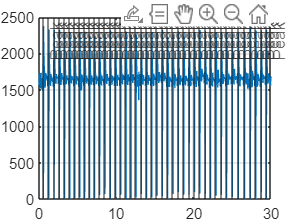

i = 140

lastTime = 0.5561

i = 316

lastTime = 1.2602

i = 487

lastTime = 1.9443

i = 656

lastTime = 2.6203

i = 826

lastTime = 3.3004

i = 990

lastTime = 3.9565

i = 1153

lastTime = 4.6086

i = 1314

lastTime = 5.2527

i = 1474

lastTime = 5.8928

i = 1633

lastTime = 6.5289

i = 1793

lastTime = 7.1690

i = 1958

lastTime = 7.8290

i = 2129

lastTime = 8.5131

i = 2302

lastTime = 9.2052

i = 2471

lastTime = 9.8813

i = 2642

lastTime = 10.5654

i = 2809

lastTime = 11.2335

i = 2972

lastTime = 11.8856

i = 3136

lastTime = 12.5417

i = 3303

lastTime = 13.2098

i = 3472

lastTime = 13.8859

i = 3642

lastTime = 14.5659

i = 3814

lastTime = 15.2540

i = 3986

lastTime = 15.9421

i = 4157

lastTime = 16.6262

i = 4329

lastTime = 17.3143

i = 4501

lastTime = 18.0024

i = 4676

lastTime = 18.7025

i = 4851

lastTime = 19.4026

i = 5027

lastTime = 20.1067

i = 5198

lastTime = 20.7908

i = 5370

lastTime = 21.4789

i = 5541

lastTime = 22.1630

i = 5719

lastTime = 22.8751

i = 5891

lastTime = 23.5631

i = 6063

lastTime = 24.2512

i = 6245

lastTime = 24.9793

i = 6438

lastTime = 25.7514

i = 6638

lastTime = 26.5515

i = 6830

lastTime = 27.3196

i = 7007

lastTime = 28.0277

i = 7179

lastTime = 28.7158

i = 7347

lastTime = 29.3879

clear
close all
clc

T_A = 4e-3;
f_A = 1/T_A;


data = transpose(load("uC_data.mat").dataOut(:,2));
%data = load("gabriel_ekg.mat").data;
BUFFERSIZE = length(data);
t = linspace(0,30,BUFFERSIZE);

peakDetected = false;

figure
plot(t, data)
%xlim([0 3])
grid
n=1;
heartTime(1) = 0;
lastTime = 0;
for i=4:BUFFERSIZE
    if data(i) <  750
        if(data(i) < data(i-1))
            if peakDetected == false
                if (t(i) - lastTime) > 0.2
                    i
                    lastTime = t(i)
                    heartTime(n) = t(i);
                    xline(t(i), '-','Peak')
                    peakDetected = true;
                    if(n>1)
                        heartRate = heartTime(n) - heartTime(n-1);
                    end
                    n = n+1;
                end
            end
        elseif data(i) > data(i-1)
            peakDetected = false;
        end
    end
end